# 2D Matlab basics

clear all, close, clc
set_defaults()

In two dimensions we will extensively use two functions for plotting:

- [meshgrid()](https://www.mathworks.com/help/matlab/ref/meshgrid.html)

- [reshape()](https://www.mathworks.com/help/matlab/ref/reshape.html)

These functions have an internal logic that is counter-intuitive and forces us to use certain convections to avoid trouble later. 

## Meshgrid()

The function meshgrid() takes two vectors **x** and **y** that contain the location of the grid points and generates matrices **X** and **Y** that are used by all 2D Matlab plotting functions, in particular [contour()](https://www.mathworks.com/help/matlab/ref/contour.html), [contourf()](https://www.mathworks.com/help/matlab/ref/contourf.html) and [surf()](https://www.mathworks.com/help/matlab/ref/surf.html).

f = @(x,y) x.*y;
g = @(x,y) y;

Nx = 4; Ny = 3; N = Nx*Ny

N = 12

x = linspace(0,1,Nx)

x =          0    0.3333    0.6667    1.0000


y = linspace(0,2,Ny)

y =      0     1     2


[X,Y] = meshgrid(x,y)

X =          0    0.3333    0.6667    1.0000
         0    0.3333    0.6667    1.0000
         0    0.3333    0.6667    1.0000


Y =      0     0     0     0
     1     1     1     1
     2     2     2     2


size(X)

ans =      3     4


In the matrices **X** and **Y**, the $y$-value increases with the row index, $i$, and the $x$-value increases with the column index, $j$.  Since we index matrices as **X**(i,j) and **Y**(i,j), the first index is the $y
$-coordinate. **This makes it natural to order our grid y-first - see below! **

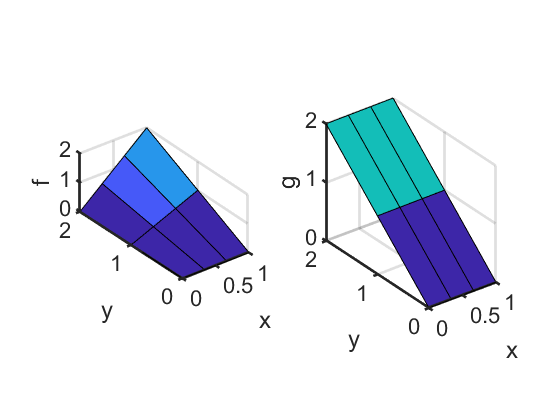

subplot 121
surf(X,Y,f(X,Y))
xlabel 'x', ylabel 'y', zlabel 'f'
pbaspect([1 2 .8])

subplot 122
surf(X,Y,g(X,Y))
xlabel 'x', ylabel 'y', zlabel 'g'
pbaspect([1 2 2*.8])

## Reshape()

The solution of the PDE is calculated as a column vector, **u**. To plot the solution **u** has to be reshaped into a matrix that is compatible with the ordering of the **X** and **Y** matrices produced by meshgrid. The Matlab function reshape() allows us to move from vectors to matrices and back. 

**1) From a matrix to a vector**

There are two options to turn a matrix into a column vector.

- [Colon operator](https://www.mathworks.com/help/matlab/ref/colon.html)

- reshape()

X

X =          0    0.3333    0.6667    1.0000
         0    0.3333    0.6667    1.0000
         0    0.3333    0.6667    1.0000


x1 = X(:)

x1 =          0
         0
         0
    0.3333
    0.3333
    0.3333
    0.6667
    0.6667
    0.6667
    1.0000


x2 = reshape(X,N,1)

x2 =          0
         0
         0
    0.3333
    0.3333
    0.3333
    0.6667
    0.6667
    0.6667
    1.0000


Note, both ways stack the columns of **X** into a column.

Of course reshape() is the more general, it allows you to transform X into any matrix or vector with the same number of elements

reshape(X,1,N)     % row vector

ans =          0         0         0    0.3333    0.3333    0.3333    0.6667    0.6667    0.6667    1.0000    1.0000    1.0000


reshape(X,Nx,Ny)   % flip the dimension of the matrix

ans =          0    0.3333    0.6667
         0    0.3333    1.0000
         0    0.6667    1.0000
    0.3333    0.6667    1.0000


**1) From vector to matrix**

Suppose the solution is given by $\mathbf{g} = g(\mathbf{x})$

soln = g(X(:),Y(:))

soln =      0
     1
     2
     0
     1
     2
     0
     1
     2
     0


To plot this solution we need to transfer it back to a matrix. To be compatible with X and Y from meshgrid this matrix has to be of size `Ny` by `Nx`!

SOLN = reshape(soln,Ny,Nx)

SOLN =      0     0     0     0
     1     1     1     1
     2     2     2     2


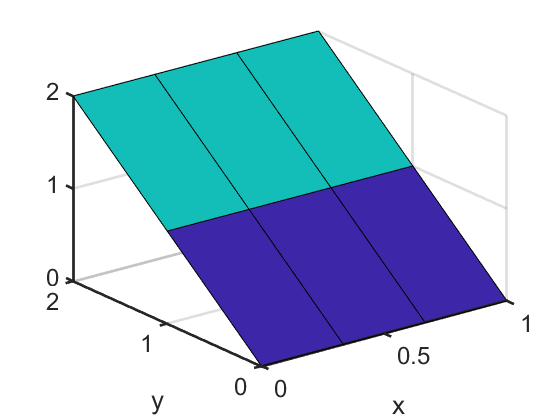

figure
surf(X,Y,SOLN)
xlabel('x'), ylabel('y')

Notice, that Ny is the first entry, because meshgrid() has a y-first ordering!

## 2D grid with y-first ordering

Given that meshgrid() has an internal y-first ordering, we use a computational grid with a y-first ordering. This way we avoid a lot of problems!

Nx = 4;
Ny = 3;
N = Nx*Ny;

x = 1:Nx;
y = 1:Ny;
dof = 1:N;

[X,Y] = meshgrid(x,y);

DOF = reshape(dof,Ny,Nx)

DOF =      1     4     7    10
     2     5     8    11
     3     6     9    12


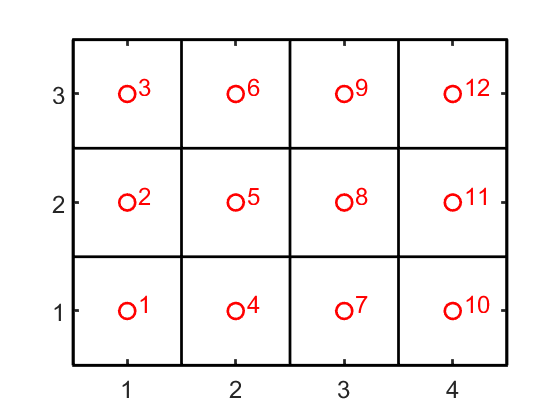


plot([.5 Nx+.5 Nx+.5 .5 .5],[.5 .5 Ny+.5 Ny+.5 .5],'k'), hold on
for i=1:Nx
    plot([x(i)+.5 x(i)+.5],[.5 Ny+.5],'k-')
    for j=1:Ny
        plot([.5 Nx+.5],[y(j)+.5 y(j)+.5],'k-')
        plot(X(j,i),Y(j,i),'ro','markerfacecolor','w')
        text(X(j,i)+.1,Y(j,i)+.07,num2str(DOF(j,i)),'fontsize',18,'color','r')
    end
end
set(gca,'xtick',[1:Nx],'ytick',[1:Ny])
axis equal tight 

## Tensor Product

Because we are discretizing the differential operators on a regular mesh the tensor product will be a key for the efficient, clean and simple implementation of the multi dimensional operators. The tensor product is also called the Kronecker product, hence the respective Matlab function is [kron()](https://www.mathworks.com/help/matlab/ref/kron.html). We will learn more about it later, but below is the basic use.

A = eye(4);
B = [1 2;...
     4 5];
 
AoB = kron(A,B)

AoB =      1     2     0     0     0     0     0     0
     4     5     0     0     0     0     0     0
     0     0     1     2     0     0     0     0
     0     0     4     5     0     0     0     0
     0     0     0     0     1     2     0     0
     0     0     0     0     4     5     0     0
     0     0     0     0     0     0     1     2
     0     0     0     0     0     0     4     5



BoA = kron(B,A)

BoA =      1     0     0     0     2     0     0     0
     0     1     0     0     0     2     0     0
     0     0     1     0     0     0     2     0
     0     0     0     1     0     0     0     2
     4     0     0     0     5     0     0     0
     0     4     0     0     0     5     0     0
     0     0     4     0     0     0     5     0
     0     0     0     4     0     0     0     5


# Auxillary functions

## set_defaults()

function [] = set_defaults()
set(0, ...
    'defaultaxesfontsize',   18, ...
    'defaultaxeslinewidth',   2.0, ...
    'defaultlinelinewidth',   2.0, ...
    'defaultpatchlinewidth',  2.0,...
    'DefaultLineMarkerSize', 12.0);
end